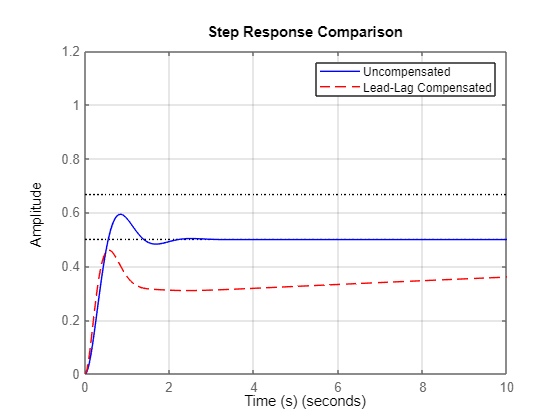

%=========================================================
% Lead-Lag Compensation for Second-Order System
% System: G(s) = num / den
% Author: Joshua Wambua
% Date: 9-Nov-2025
%=========================================================

clc; clear; close all;

%% 1. Define the plant
s = tf('s');
num = 9;                  % Numerator of G(s), change for each case
den = [1 4 9];            % Denominator coefficients [s^2 b s c]
G = tf(num, den);

%% 2. Lead compensator design
K_lead = 2;               % Lead compensator gain
z_lead = 1;               % Lead zero
p_lead = 5;               % Lead pole
G_lead = K_lead * (s + z_lead)/(s + p_lead);

%% 3. Lag compensator design
z_lag = 0.05;             % Lag zero
p_lag = 0.01;             % Lag pole
G_lag = (s + z_lag)/(s + p_lag);

%% 4. Combined compensator
G_comp = G_lead * G_lag;
L_comp = G_comp * G;
T_comp = feedback(L_comp, 1);

T0 = feedback(G, 1);

%% 5. Step response comparison
figure;
step(T0, 'b', T_comp, 'r--');
grid on;

% Set axis limits to improve visualization
xlim([0 10]);  % Start from 0, but can adjust to avoid starting at the x-axis if needed
ylim([0 1.2]);  % Adjust the y-axis range for better visualization

% Labels and title
legend('Uncompensated','Lead-Lag Compensated');
title('Step Response Comparison');
xlabel('Time (s)');

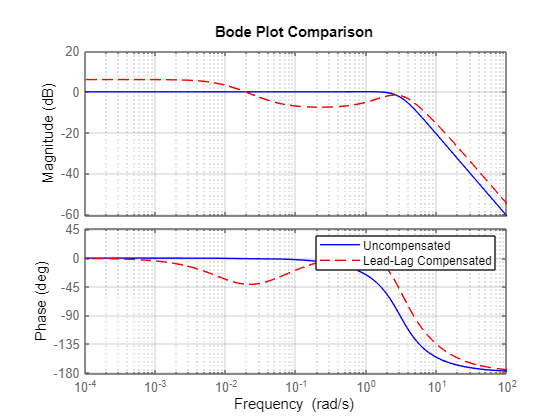

ylabel('Amplitude');

ylabel('Amplitude');

%% 6. Bode plot comparison
figure;
bode(G, 'b', L_comp, 'r--');
grid on;
legend('Uncompensated','Lead-Lag Compensated');
title('Bode Plot Comparison');

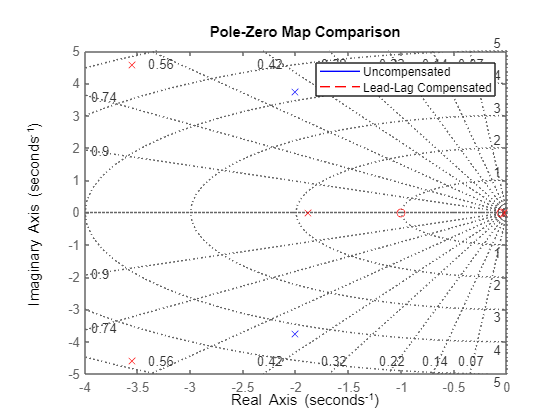


%% 7. Pole-Zero map comparison
figure;
pzmap(T0, 'b', T_comp, 'r--');
grid on;
legend('Uncompensated','Lead-Lag Compensated');
title('Pole-Zero Map Comparison');


%% 8. Step response info
disp('=== Step Response Info ===');

=== Step Response Info ===


disp('Uncompensated System:');

Uncompensated System:


disp(stepinfo(T0));

         RiseTime: 0.3735
    TransientTime: 1.9487
     SettlingTime: 1.9487
      SettlingMin: 0.4659
      SettlingMax: 0.5932
        Overshoot: 18.6319
       Undershoot: 0
             Peak: 0.5932
         PeakTime: 0.8289



disp('Lead-Lag Compensated System:');

Lead-Lag Compensated System:


disp(stepinfo(T_comp));

         RiseTime: 81.3214
    TransientTime: 156.7512
     SettlingTime: 156.7512
      SettlingMin: 0.6000
      SettlingMax: 0.6663
        Overshoot: 0
       Undershoot: 0
             Peak: 0.6663
         PeakTime: 322.3509




dc0 = dcgain(T0);
dc1 = dcgain(T_comp);
fprintf('\nUncompensated DC Gain = %.4f (Ess = %.4f)\n', dc0, 1-dc0);


Uncompensated DC Gain = 0.5000 (Ess = 0.5000)


fprintf('Compensated DC Gain = %.4f (Ess = %.4f)\n', dc1, 1-dc1);

Compensated DC Gain = 0.6667 (Ess = 0.3333)
